# Boeing 747-200 Analysis

## Cleaning

% Milestone01Codefinal
clear all; clc;

## Loading

% Create BACJ Airfoil Data
tempAlpha = [-5:1:13]';
tempCl = [-0.3505;-0.2514;-0.1493;-0.0318;0.0912;0.2133;0.3048;0.318;0.3925;0.4889;0.5855;0.6808;0.7744;0.8721;0.9729;1.061;1.1263;0.9165;0.7781];
tempCd = [0.00953;0.00852;0.00741;0.00584;0.0055;0.00509;0.00506;0.00743;0.00948;0.01033;0.01132;0.01256;0.01441;0.01634;0.02052;0.02498;0.03112;0.07156;0.14138];
BACJAirfoilData = table(tempAlpha, tempCl, tempCd, 'VariableNames', {'Alpha', 'Cl', 'Cd'})

BACJAirfoilData = 19×3 table
    Alpha      Cl         Cd   
    _____    _______    _______
     -5      -0.3505    0.00953
     -4      -0.2514    0.00852
     -3      -0.1493    0.00741
     -2      -0.0318    0.00584
     -1       0.0912     0.0055
      0       0.2133    0.00509
      1       0.3048    0.00506
      2        0.318    0.00743
      3       0.3925    0.00948
      4       0.4889    0.01033
      5       0.5855    0.01132
      6       0.6808    0.01256
      7       0.7744    0.01441
      8       0.8721    0.01634
      9       0.9729    0.02052
     10        1.061    0.02498


% Insert given CL and CD values
tempCL = [0.5922;0.5683;0.5473;0.5240;0.4962;0.4724;0.4486;0.4219;0.3981;0.3719;0.3486;0.3234;0.3001;0.2735;0.2493;0.2236;0.2009;0.1738;0.1525;0.1255;0.1037;0.0781;0.0550;0.0285;0.0039];
tempCD = [0.0342;0.0323;0.0306;0.0290;0.0273;0.0259;0.0247;0.0232;0.0224;0.0212;0.0203;0.0194;0.0186;0.0182;0.0174;0.0171;0.0169;0.0165;0.0165;0.0163;0.0165;0.0166;0.0168;0.0173;0.0180];
givenDragData  = table(tempCL, tempCD, 'VariableNames', {'CL', 'CD'})

givenDragData = 25×2 table
      CL        CD  
    ______    ______
    0.5922    0.0342
    0.5683    0.0323
    0.5473    0.0306
     0.524     0.029
    0.4962    0.0273
    0.4724    0.0259
    0.4486    0.0247
    0.4219    0.0232
    0.3981    0.0224
    0.3719    0.0212
    0.3486    0.0203
    0.3234    0.0194
    0.3001    0.0186
    0.2735    0.0182
    0.2493    0.0174
    0.2236    0.0171


% Load Tempest Data
% load("TempestData.mat")

## Variables

AR = 7;              % Aspect ratio
ran = 12150;         % Range in km
fCap = 204.36;       % Fuel capacity in m^3
minThrust = 206;     % Minimum thrust in kN
maxThrust = 243.5;   % Maximum thrust in kN
oew = 170.1;         % Operating empty weight in tonnes
mtow = 377.8;        % Maximum takeoff weight in tonnes
wingspan = 59.6;     % Wing span in m
wingArea = 511;      % Wing area in m^2
wettedArea = 3104.2; % Aircraft wetted area m^2 (using precise measurements)
wingSweep = 37.5;    % Wing sweep in degrees
cabWidth = 6.08;     % Cabin width in m
Cfe = 0.0030;        % Equivalent skin friction coefficient for civil transport aircraft type
spanEF = .9;         % Span efficiency factor

## Lift Curve Comparison

fit2D = polyfit(BACJAirfoilData.Alpha, BACJAirfoilData.Cl, 1); % Best fit line for Cl vs AOA
a0 = fit2D(1);                                                 % Save value of slope
fit2D = polyfit(BACJAirfoilData.Cl, BACJAirfoilData.Alpha, 1); % Best fit line after flipping axes
angle0Lift = polyval(fit2D, 0);                                % Angle of attack at 0 lift
a = liftSlope3D(a0, AR, spanEF);                               % Calculate lift curve slope
calcCL = liftCoef(a, BACJAirfoilData.Alpha, angle0Lift)        % Calculate coefficient of lift for finite 3D wing

calcCL =    -0.2224
   -0.1589
   -0.0954
   -0.0318
    0.0317
    0.0952
    0.1587
    0.2222
    0.2857
    0.3492


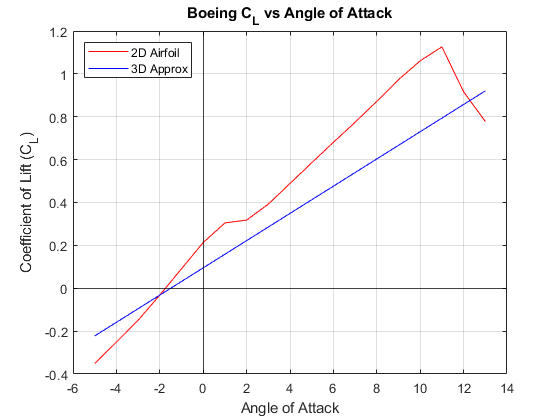


% Plot for task 1
plot(BACJAirfoilData.Alpha, BACJAirfoilData.Cl, 'r')
hold on;
plot(BACJAirfoilData.Alpha, calcCL, 'b')
xline(0, 'k')
yline(0, 'k')
hold off;
grid on;
xlabel('Angle of Attack')
ylabel('Coefficient of Lift (C_L)')
title('Boeing C_L vs Angle of Attack')
legend('2D Airfoil', '3D Approx', 'Location', 'northwest')

## Drag Polar Comparison

% Flat plate approximation
ReL = 1000000;                                                % total global Re 
WingL = 14.27;                                                % m
RhoVoverMu = ReL/WingL;                                       % Value of rho*V/mu for SLUF
ReCr = 5*(10^5);                                              % Critical Re
xCr = ReCr/RhoVoverMu;                                        % Critical Distance
CfTurbTotal = 0.074/(ReL^0.2);                                % Total Wing Turbulent Cf
CfTurbLeft = 0.0592/(ReCr^0.2);                               % Turbulent Cf to be subtracted from total
CfLamLeft = 0.664/sqrt(ReCr);                                 % Laminar Cf
CfTotal = 2*(CfTurbTotal - CfTurbLeft + CfLamLeft);           % Total Cf for both wings
VCruise = 907;                                                % km/h
V = VCruise/3600*1000;                                        % m/s
rho = 0.38857;                                                % kg/m^3
q = 1/2*rho*(V^2);                                            % Dynamic pressure                                               % m^2, Planform area
Df = 2*wingArea*CfTotal;                                      % N, Drag Force
CdW = Df / (q*wingArea);                                      % Wing drag coef
CdF = 0.00136;                                                % Fuselage drag coef using turbulent approximation
Cd = CdW + CdF;                                               % Total aircraft drag using flat plate approx.

CDWing = dragCoefWing(calcCL, BACJAirfoilData.Cd, AR, spanEF) % Calculate finite wing drag polar

CDWing =     0.0120
    0.0098
    0.0079
    0.0059
    0.0056
    0.0055
    0.0063
    0.0099
    0.0136
    0.0165


e0 = oswaldsRaymer(AR);                                       % Calculate Oswald's efficiency number using Raymer formula
e02 = oswaldsObert(AR);                                       % Calculate Oswald's efficiency number using Obert formula
k1 = 1 / (pi * e0 * AR);                                      % Calculate k1 value
CDmin = skinFrictionDrag(Cfe, wettedArea, wingArea);          % Find minimum coefficient of drag
fitDragWing = polyfit(CDWing, calcCL, 2);                     % Create best fit line for finding coefficient of lift at point of minimum coefficient of drag
CLminD = polyval(fitDragWing, min(CDWing));                   % Calculate coefficient of lift at point of minimum coefficient of drag
k2 = -2 * k1 * CLminD;                                        % Find k2 value for use in equation 7
CD0 = minCoefDrag(CDmin, k1, CLminD);                         % Calculate parasite drag

CDwhole4 = completeDragPolarGen(CD0, k1, calcCL)              % Coefficient of drag using equation 4

CDwhole4 =     0.0210
    0.0197
    0.0188
    0.0184
    0.0184
    0.0188
    0.0197
    0.0210
    0.0227
    0.0249


CDwhole6 = completeDragPolarNZVL(CDmin, k1, calcCL, CLminD)   % Coefficient of drag using equation 6

CDwhole6 =     0.0219
    0.0204
    0.0192
    0.0185
    0.0182
    0.0184
    0.0190
    0.0200
    0.0215
    0.0234


CDwhole6Flat = completeDragPolarNZVL(Cd, k1, calcCL, CLminD)  % Coefficient of drag using equation 7

CDwhole6Flat =     0.0051
    0.0035
    0.0023
    0.0016
    0.0014
    0.0015
    0.0021
    0.0032
    0.0046
    0.0066


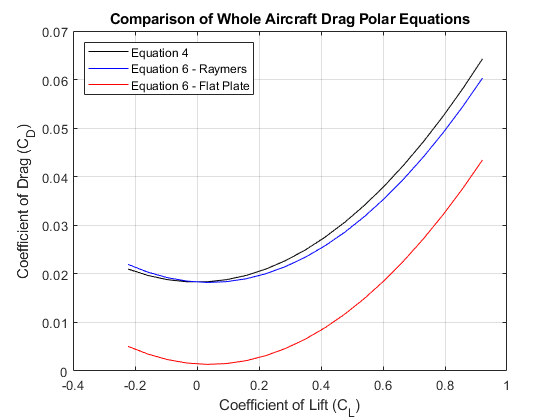


% Plot comparisons between coefficients of lift using various equations
plot(calcCL, CDwhole4, 'k');
hold on;
plot(calcCL, CDwhole6, 'b');
plot(calcCL, CDwhole6Flat, 'r');
hold off;
grid on;
xlabel('Coefficient of Lift (C_L)')
ylabel('Coefficient of Drag (C_D)')
title('Comparison of Whole Aircraft Drag Polar Equations')
legend('Equation 4', 'Equation 6 - Raymers', 'Equation 6 - Flat Plate', 'Location', 'Northwest')

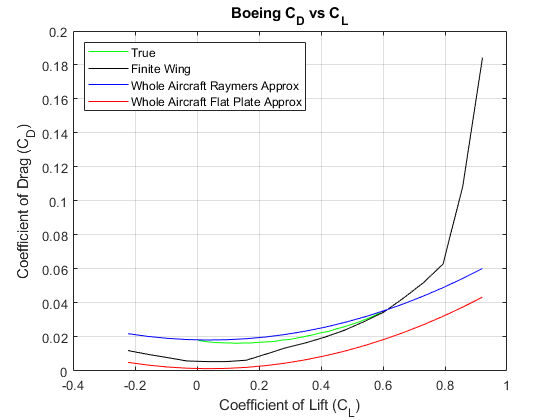


% Plots for task 2
plot(givenDragData.CL, givenDragData.CD, 'g');
hold on;
plot(calcCL, CDWing, 'k');
plot(calcCL, CDwhole6, 'b');
plot(calcCL, CDwhole6Flat, 'r');
hold off;
grid on;
xlabel('Coefficient of Lift (C_L)')
ylabel('Coefficient of Drag (C_D)')
title('Boeing C_D vs C_L')
legend('True', 'Finite Wing', 'Whole Aircraft Raymers Approx', 'Whole Aircraft Flat Plate Approx', 'Location', 'NorthWest')

## Performance Comparisons

% L/D Max - Calculated
weight = (mtow * 1000) * 9.81;                                           % Weight in N
alt = 35000 / 3.281;                                                     % Altitude in m
[~, ~, ~, rhoAlt] = atmoscoesa(alt);                                     % Density at given altitude

LoD = calcCL./CDwhole6;                                                  % Calculate CL over CD
LoDMax = max(LoD)                                                        % Find max value of CL vs CD

LoDMax = 17.0214

% Repeat above steps for given CL and CD 747 data
givenLoD = givenDragData.CL ./ givenDragData.CD;
givenLoDMax = max(givenLoD)

givenLoDMax = 18.2394


% Polyfit to see if we could get more accurate values
fitLoD = polyfit(BACJAirfoilData.Alpha, LoD, 2);
aoa = [-5:.1:13];
LoDPlus = polyval(fitLoD, aoa);
LoDPlusMax = max(LoDPlus)

LoDPlusMax = 17.4726

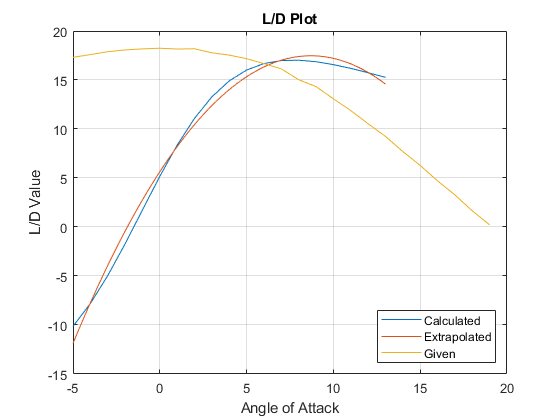


% Plot all 3 CL vs CD arrays
plot(BACJAirfoilData.Alpha, LoD)
hold on;
plot(aoa, LoDPlus)
plot([-5:1:(length(givenLoD)-6)], givenLoD)                              % This graph is poorly aligned because AOA data not given
hold off;
grid on;
title('L/D Plot')
xlabel('Angle of Attack')
ylabel('L/D Value')
legend('Calculated', 'Extrapolated', 'Given', 'Location', 'SouthEast')


% Calculate CL value at max CL vs CD (to be used in velocity calculations)
maxCL = calcCL(LoD == LoDMax)                                            % CL value for calculated CL data

maxCL = 0.6033

maxCLGiven = givenDragData.CL(givenLoD == givenLoDMax)                   % CL value for given CL data

maxCLGiven = 0.4724


% Velocity for Max Glide Range, Velocity for Max Powered Endurance
Vinf = sqrt(2*weight / (maxCL * rhoAlt * wingArea))                      % Velocity in m/s

Vinf = 251.6735

VinfGiven = sqrt(2*weight / (maxCLGiven * rhoAlt * wingArea))            % Velocity in m/s

VinfGiven = 284.4065

rangeCalc = alt * LoDMax                                                 % Maximum glide range given CL value

rangeCalc = 1.8158e+05

rangeCalcGiven = alt * givenLoDMax                                       % Maximum glide range given CL value

rangeCalcGiven = 1.9457e+05


% Velocity for Max Powered Range
% Recalculate max CL/CD value given powered range equation (sqrtCL / CD)
newLoD = (abs(calcCL).^.5)./CDwhole6;
newMaxLoD = max(newLoD)

newMaxLoD = 25.2332

newGivenLoD = (abs(givenDragData.CL).^.5) ./ givenDragData.CD;
newMaxGivenLoD = max(newGivenLoD)

newMaxGivenLoD = 29.4524

% Calculate CL value at new L/D max and use in velocity function
newMaxCL = calcCL(newLoD == newMaxLoD)

newMaxCL = 0.3492

newMaxCLGiven = givenDragData.CL(newGivenLoD == newMaxGivenLoD)

newMaxCLGiven = 0.3001

VinfPowered = sqrt(2*weight / (newMaxCL * rhoAlt * wingArea))            % Velocity in m/s

VinfPowered = 330.7809

VinfGivenPowered = sqrt(2*weight / (newMaxCLGiven * rhoAlt * wingArea))  % Velocity in m/s

VinfGivenPowered = 356.8300


% Flat Plate
LoDFlat = calcCL./CDwhole6Flat;                                                  % Calculate CL over CD
LoDMaxFlat = max(LoDFlat)                                                        % Find max value of CL vs CD

LoDMaxFlat = 74.5319


% Calculate CL value at max CL vs CD (to be used in velocity calculations)
maxCLFlat = calcCL(LoDFlat == LoDMaxFlat)                                        % CL value for calculated CL data

maxCLFlat = 0.1587


% Velocity for Max Glide Range, Velocity for Max Powered Endurance
VinfFlat = sqrt(2*weight / (maxCLFlat * rhoAlt * wingArea))                      % Velocity in m/s

VinfFlat = 490.6999

rangeCalcFlat = alt * LoDMaxFlat                                                 % Maximum glide range given CL value

rangeCalcFlat = 7.9507e+05


% Velocity for Max Powered Range
% Recalculate max CL/CD value given powered range equation (sqrtCL / CD)
newLoDFlat = (abs(calcCL).^.5)./CDwhole6Flat;
newMaxLoDFlat = max(newLoDFlat)

newMaxLoDFlat = 201.9164

% Calculate CL value at new L/D max and use in velocity function
newMaxCLFlat = calcCL(newLoDFlat == newMaxLoDFlat)

newMaxCLFlat = 0.0952

VinfPoweredFlat = sqrt(2*weight / (newMaxCLFlat * rhoAlt * wingArea))            % Velocity in m/s

VinfPoweredFlat = 633.6053

## Consolodate and Save Data

% finalTableTopRow = table(LDMcalc, glideR_v_calc, powerR_v_calc, powerE_v_calc, LDMcalcalt, glideR_v_calcalt, powerR_v_calcalt, powerE_v_calcalt, LDMtrue, glideR_v_true, powerR_v_true, powerE_v_true, ...
%     'VariableNames', {'LoverD', 'VelocityGlideRange', 'VelocityPoweredRange', 'VelocityPoweredEndurance', 'LoverDFlat', 'VelocityGlideRangeFlat', 'VelocityPoweredRangeFlat', 'VelocityPoweredEnduranceFlat', 'LoverDTrue', 'VelocityGlideRangeTrue', 'VelocityPoweredRangeTrue', 'VelocityPoweredEnduranceTrue'});
% finalTableBottomRow = table(LoDMax, Vinf, VinfPowered, Vinf, LoDMaxFlat, VinfFlat, VinfPoweredFlat, VinfFlat, givenLoDMax, VinfGiven, VinfGivenPowered, VinfGiven, ...
%     'VariableNames', {'LoverD', 'VelocityGlideRange', 'VelocityPoweredRange', 'VelocityPoweredEndurance', 'LoverDFlat', 'VelocityGlideRangeFlat', 'VelocityPoweredRangeFlat', 'VelocityPoweredEnduranceFlat', 'LoverDTrue', 'VelocityGlideRangeTrue', 'VelocityPoweredRangeTrue', 'VelocityPoweredEnduranceTrue'});
% finalTable = [finalTableTopRow; finalTableBottomRow];
% finalTable.Properties.RowNames = {'Tempest', 'Boeing'};
% finalTable
% 
% writetable(finalTable, 'FinalData.csv')

## Functions

function out = liftSlope3D(a0, AR, e) % Equation 1
% Calculates the 3D lift slope
    out = a0 ./ (1 + ((57.3 .* a0) ./ (pi .* e .* AR)));
end

function out = liftCoef(a, alpha, alphaL0) % Equation 2
% Calculates the coefficient of lift
    out = a .* (alpha - alphaL0);
end

function out = dragCoefWing(CL, Cd, AR, e) % Equation 3
% Calculate 3D wing drag polar
    out = Cd + (CL.^2 ./ (pi .* e .* AR));
end

function out = completeDragPolarGen(CD0, k1, CL) % Equation 4
% Calculates drag polar for entire aircraft
    out = CD0 + (k1 .* CL.^2);
end

function out = completeDragPolarNZVL(CDmin, k1, CL, CLminD) % Equation 6
% Calculates whole aircraft drag polar assuming minimum drag occurs at
% non-zero value of lift (NZVL)
    out = CDmin + (k1 .* (CL - CLminD).^2);
end

function out = completeDragPolarExp(CD0, k1, CL, k2) % Equation 7
% Expanded form of NZVL equation
    out = CD0 + (k1 .* CL.^2) + (k2 .* CL);
end

function out = minCoefDrag(CDmin, k1, CLminD) % Equation 9
% Calculate initial whole aircraft CD
    out = CDmin + (k1 .* CLminD.^2);
end

function out = skinFrictionDrag(Cfe, Swet, Sref) % Equation 10
% Calculates whole aircraft skin friction drag given equivalent skin
% friction coefficient, wetted area, wing planform area
    out = Cfe .* (Swet ./ Sref);
end

function out = oswaldsRaymer(AR) % Equation 12
% Calculate Oswald's efficiency number
    out = (1.78 .* (1 - (0.045 .* AR.^0.68))) - 0.64;
end

function out = oswaldsObert(AR)
% Calculate Oswald's efficiency number using Obert's equation
    Q = 1.05;
    P = 0.007 * pi;
    out = 1 ./ (Q + P.*AR);
end